# LEDS Exam: February 16, 2022

# Project assignment

clear all
close all
addpath ./Functions;

You will be asked to solve an identification problem in which measurements from the system are available **(1)** and a classification problem were training features are available and try it on a test set **(2)**.

## Exercise 1: Estimation (both SysID and LEDS)

In this exercise you are asked to estimate an unknown linear model.

To gather system measurements at any point in your code call the function `IdentifyThis.p `with the following inputs:

- Number of samples (`integer`)

N=10000;

- Your surname and name with no accents nor special characters (`string`)

Student = 'Bamundo Salvatore';

- Your matriculation number (`string`)

Matriculation = '0000983702';

which finally results in

[Measurements] = IdentifyThis(N,Student,Matriculation);

To collect the measurements it is advised to use this piece of code

u=Measurements.u;
y=Measurements.y;

Then, the identification problem should be solved following the step below:

- **Understand the model structure**: The provided signals refer to either a AR or a ARX model. You should get the structure straight away from the measurements. If you get an AR model, plot the output autocorrelations up to delay 10. If you get an ARX plot input autocorrelations up to delay 10. Then, comment the plot.

- **Define the required estimation algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to implement a time-weighted recursive version of the estimation algorithm.

- **Estimate the model order: **describe the criteria you plan to use and add brief description of the matlab function you implemented to do that.

- **Validate the model: **describe the criteria you plan to use to get model validation and add a description of the matlab functions you implemented to do that. Finally, compute the covariance matrix of the estimated model's parameters.

### Exercise 1.0: Difference between AR and ARX models

Before starting, I need to explain what is the difference between an **ARX** (**A**uto**R**egressive e**X**ogenous) and an **AR** (**A**uto**R**egressive) model in order to understand how can I distinguish them.

The main difference is, of course, the letter **'X'**. It means that ARX models have inputs (the so-called e**X**ogenous part), whereas the AR not.

#### ARX models

From theory, we know that the ARX model is so built:

            
$$y(t) + a_1 y(t-1) +\dots + a_n y(t-n)= b_1u(t-1) + \dots + b_nu(t-n) + e(t)       
 $$
            

In wich we measure the output $y(t)$, with $e(t)$ being a *white process *with $0$ mean and variance $\sigma_e^2$. 

#### AR models 

An AR model of order $n$ is so built:


$$y(t) + a_1 y(t-1) + \dots + a_ny(t-n)  = e(t)$$


in wich we measure the output $y(t)$, with $e(t)$ being a *white process *with $0$ mean and variance $\sigma_e^2$. 

As it is possible to notice, in the latter equation there is no input.

### Exercise 1.1: **Understand the model structure**

Thus, a possible choise that I can use to understand what kind of model I am dealing with is to observe what is the plot of the input and to check if actually it is present (different from zero):

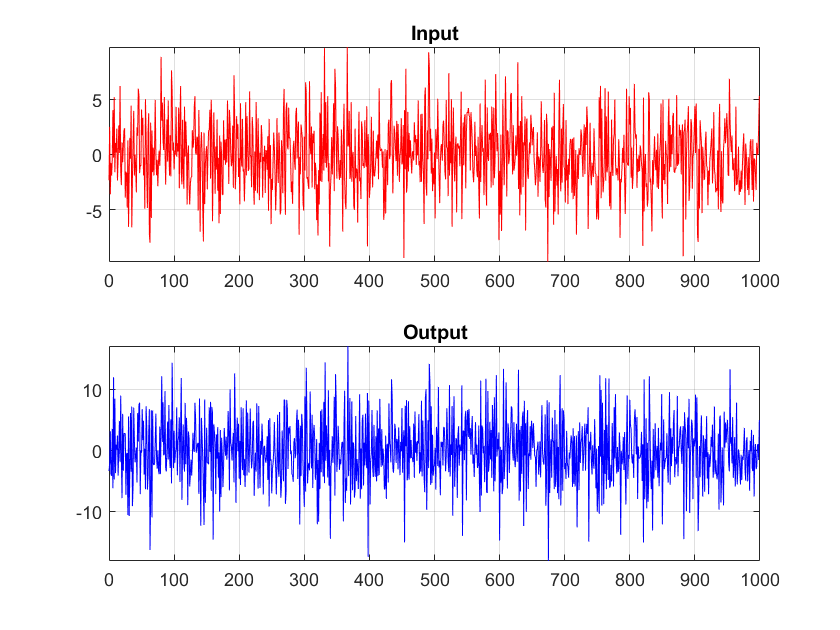

time=[0:1:N-1]'; % Time in samples
figure('Name','Input and Output plots','NumberTitle','off');

subplot(2,1,1);
plot(time(1:N/10),u(1:N/10), '-r')
ylim([-max(u(1:N/10)) max(u(1:N/10))])
grid on
title('Input')

subplot(2,1,2); 
plot(time(1:N/10),y(1:N/10), '-b')
ylim([min(y(1:N/10)) max(y(1:N/10))])
grid on
title('Output')

Since the input is present (clearly), I can state that the model originated by my name is an **ARX** model.

Let's analyze now what is the plot of the input autocorrelations up to delay 10:

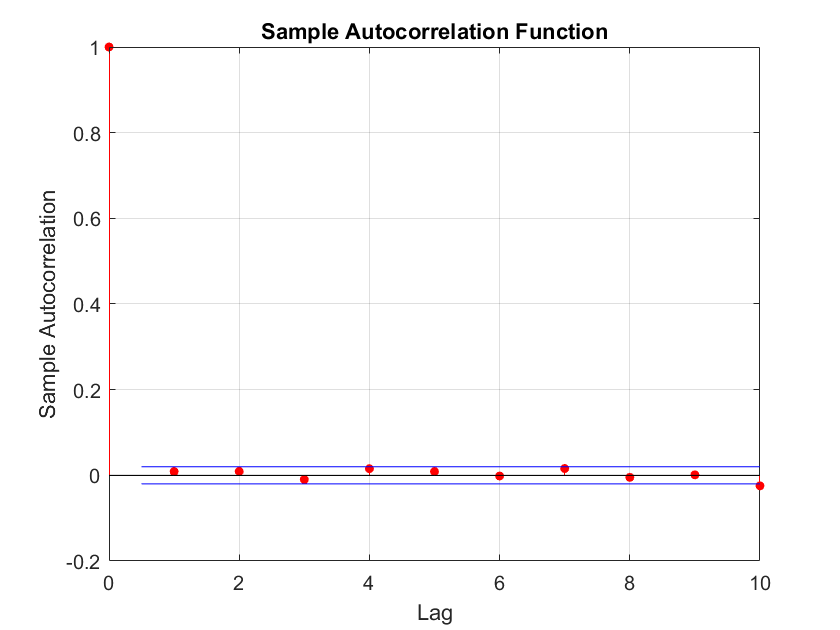

figure('Name','Input autocorrelations up to delay 10','NumberTitle','off');
autocorr(u,'NumLags',10);

This result shows us that in reality, as regards the autocorrelation (that in Matlab it is the normalized autocorrelaction), the input behavies as a white noise. In fact, we have that the autocorrelation is different from zero only when $\tau \;$(time lag) is zero, otherwise it is zero. It means that the input is completely uncorrelated with its past.

For this reason, we can state that it is a persistently exicting (p.e.) signal of any order.

### Exercise 1.2: **Define the required estimation algorithm**

#### **A brief recap about the general LS method**

Consider again the ARX model with order n (and 2n parameters).

            
$$y(t) + a_1 y(t-1) +\dots + a_n y(t-n)= b_1u(t-1) + \dots + b_nu(t-n) + e(t)       
 $$
            
$$\left(1\right)$$


Notice that in Matlab, N represents the number of samples while in our slides (theory), it represents the number of total equations (namely $\textrm{#samples}-n$ ).

Starting from (1), we can easly obtain the matrix form:

            
$$y(t)=\varphi^T(t) \theta + e(t)
$$


where the regressor is defined as:

            
$$\varphi(t)=[ -y(t-1)\  \dots \ -y(t-n)    \quad u(t-1) \ \dots \ u(t-n)]^T$$


which in general can be seen as:

            
$$\varphi(t)=[-\varphi_y^T(t) \quad \varphi_u^T(t)]^T
$$


and the parameter vector is defined as:

             
$$\theta = [a_1 \ \dots \ a_n \quad b_1 \ \dots \ b_n]^T
$$


Once the ARX process is ready (by using the filter functions we have already seen during the classes $y(t)=\frac{B(z^{-1})}{A(z^{-1})}u(t) + \frac{e(t)}{A(z^{-1})}$), we can proceed with trying to solve the identification problem, namely we will try to get $\theta^*$ coefficients: $a$ and $b$ as previously defined.

In the **Least Squares** (LS) method we want to find the estimate $\hat\theta$ that minimizes the following loss function (given $y\;\textrm{and}\;u$):

            
$$J(\hat\theta)=\frac{1}{N}\sum_{t=1}^N \epsilon^2(t)=\frac{1}{N}\epsilon^T\epsilon=\frac{1}{N}\|\epsilon\|^2
$$


where

            
$$\varepsilon=[\varepsilon(1) \  \varepsilon(2) \ \ldots\  \varepsilon(N)]^{T}$$


from

            
$$Y=H\hat{\theta}+\epsilon$$


where 

            
$$Y=\left[\begin{array}{lll}
y(1) y(2) & \ldots & y(N)
\end{array}\right]^{T}, \quad H=\left[\begin{array}{c}
\varphi^{T}(1) \\
\varphi^{T}(2) \\
\vdots \\
\varphi^{T}(N)
\end{array}\right] = \left[-H_y \quad H_u \right]$$


with

            $H_{u}(n)=\left[\begin{array}{cccc}
u(0) & u(-1) & \cdots & u(1-n) \\
u(1) & u(0) & \cdots & u(2-n) \\
\vdots & \vdots & \cdots & \vdots \\
u(N-1) & u(N-2) & \cdots & u(N-n)
\end{array}\right]$, $H_{y}(n)=\left[\begin{array}{cccc}
y(0) & y(-1) & \cdots & y(1-n) \\
y(1) & y(0) & \cdots & y(2-n) \\
\vdots & \vdots & \cdots & \vdots \\
y(N-1) & y(N-2) & \cdots & y(N-n)
\end{array}\right]$

where $H$ is the *Hankel* matrix. Our loss function can be regarded also as 

            
$$J(\hat\theta)=\frac{1}{N}\|Y-H \hat\theta\|^{2}$$


What do negative samples mean in the Hankel matrix?

well, assume to have:

            
$$u(1), \ u(2)\ \dots \ u(M) \\ 
y(1), \ y(2)\ \dots \ y(M)$$


Where M is the number of samples (pay attention, in Matlab it is called N).

suppose to have M = 100 and the order n = 3:

            
$$y(t) = -a_1 y(t-1) - a_2 y(t-2) - a_3 y(t-3) + b_1u(t-1) + b_2 u(t-2) + b_3u(t-3) + e(t)       
 $$


now, since y depends on itself and on u at the previous 3 samples (in general n samples), we can NOT start from the sample at time 0, it because we have no other previous sample (obviously). So, the trick that we use is to start from the third sample (in general from the "n-th" sample) and finish to the (100-n)th sample (N in genarl).

In this way, we can compute all the computations:

                             
$$\begin{array}{l}
\mathit{\mathbf{y}}\left(1\right),\;\mathit{\mathbf{y}}\left(2\right),\;\ldotp \ldotp \ldotp \;,\;\mathit{\mathbf{y}}\left(\mathit{\mathbf{n}}\right),\;y\left(1+n\right),y\left(2+n\right),\;\ldotp \ldotp \ldotp ,y\left(M\right)\\
\mathit{\mathbf{y}}\left(1\right),\mathit{\mathbf{u}}\left(2\right),\;\;\ldotp \ldotp \ldotp \;,\;\mathit{\mathbf{u}}\left(\mathit{\mathbf{n}}\right),\;u\left(1+n\right),u\left(2+n\right),\;\ldotp \ldotp \ldotp ,u\left(M\right)
\end{array}$$
            
$$\left(2\right)$$


That is, changing notation, by subtracting $n$ from all the samples in (2):

            
$$\begin{array}{l}
\mathit{\mathbf{y}}\left(1-\mathit{\mathbf{n}}\right),\;\mathit{\mathbf{y}}\left(2-\mathit{\mathbf{n}}\right),\;\ldotp \ldotp \ldotp \;,\;\mathit{\mathbf{y}}\left(0\right),\;y\left(1\right),y\left(2\right),\;\ldotp \ldotp \ldotp ,y\left(N\right)\\
\mathit{\mathbf{y}}\left(1-\mathit{\mathbf{n}}\right),\mathit{\mathbf{u}}\left(2-\mathit{\mathbf{n}}\right),\;\;\ldotp \ldotp \ldotp \;,\;\mathit{\mathbf{u}}\left(0\right),\;u\left(1\right),u\left(2\right),\;\ldotp \ldotp \ldotp ,u\left(N\right)
\end{array}$$


where N (using slides' notation) is $N=\textrm{#samples}-n$ (where #samples in Matlab is N and it is M in this notation).

The **LS method** has a closed form solution, that is proven to be

            
$$\hat{\theta}=\left(\frac{H^{T} H}{N}\right)^{-1} \frac{H^{T} Y}{N}=\left(\frac{1}{N} \sum_{t=1}^{N} \varphi(t) \varphi^{T}(t)\right)^{-1} \frac{1}{N} \sum_{t=1}^{N} \varphi(t) y(t)$$


#### Time-weighted recursive version of LS (RWLS)

Now, we need to implement the RWLS.

Before starting with the implementation, I would like to explain in brief what is **R**ecursive **L**east **S**quare and why we use it.

Let $\hat{\theta \;} \left(t-1\right)$ be a LS estiamte obtained from data collected up to time $t-1$:


$$\hat{\theta}(t-1)=\left(\frac{1}{N}\sum_{k=1}^{t-1} \varphi(k) \varphi^{T}(k)\right)^{-1}\frac{1}{N} \sum_{k=1}^{t-1} \varphi(k) y(k)$$
    

The reason why recursive algorithms are used are plenty, these are the main ones:

- They require less memory with respect to their batch counter part, since not all the data are stored;

- They may have more computationally efficient forms, requiring less time to perform the same operation (the version with matrix inversion lemma);

- They can be used on-line (for tracking).

The standard LS is not able to track changes in the underlying ARX coefficients producing the input and output signals nor the RLS versions done so far. To show that we introduce a second ARX process of the same order.

Instead of using the classic RLS methods, we will use RWLS.

This recursive algorithm has the same fundamental of the classical RLSs but in this case we want to track parameter variations (*real time identification*); in other words, we want to give less iportance to past data and more importance to recent data:


$$J(\hat\theta)=\sum_{t=1}^N \lambda^{N-t}\ \epsilon^2(t)=\epsilon^TW\epsilon
$$
 

Where


$$W=\textrm{diag}\left\lbrack \lambda {\;}^{N-1} \;\lambda {\;}^{N-2} \;\cdots \lambda \;1\;\right\rbrack$$


and $\lambda \;,0<\lambda <1$ is the **forgetting factor**. We have


$$\hat\theta=(\sum_{t=1}^N \lambda^{N-t}\ \varphi(t)\varphi^T(t))^{-1}\sum_{t=1}^N \lambda^{N-t}\ \varphi(t)y(t)
$$
 

Recursive wighted LS: determine a recursive form of


$$\hat\theta(t)=(\sum_{k=1}^t \lambda^{N-k}\ \varphi(k)\varphi^T(k))^{-1}\sum_{k=1}^t \lambda^{N-k}\ \varphi(k)y(k)
$$
 

#### Implementation of RWLS I

Define 


$$\sum_{k=1}^{t\;} \lambda {\;}^{t-k} \varphi \;\left(k\right)\varphi {\;}^T \left(k\right)$$


 then:

- 
$$S\left(t\right)=\lambda \;S\left(t-1\right)+\varphi \left(t\right)\varphi {\;}^T \left(t\right)$$


- 
$$K\left(t\right)=S^{-1} \left(t\right)\varphi \left(t\right)$$


- 
$$\epsilon \left(t\right)=y\left(t\right)-\varphi^T \left(t\right)\theta^ˆ \left(t-1\right)$$


- 
$$\theta^ˆ \left(t\right)=\theta^ˆ \left(t-1\right)+K\left(t\right)\epsilon \left(t\right)\;$$


The computations to arrive to these steps are just algebraic manipulations (I explained them in the first question of the written exam of the 13th january!).

To implement this function (called ***myRWLS_I.m***), since it is a recursive formula, of course I used a **for loop**. Before using it, I initialized $\theta^ˆ \left(0\right)$ equal to zero (of course it could be initialized better) and then I computed $\varphi \left(1\right)$. Once I did it, I computed in order $S\left(1\right),K\left(1\right),\epsilon \left(1\right)\;\textrm{and}\;\theta^ˆ \left(1\right)$. After computing them, I entered in the for loop in which I used recursively the updated values by using the above steps for each iteration.

% suppose that the order of the model is n = 4 and lambda is 0.98
nn = 4;
lambda = 0.98;
Theta_RWLS_I_=myRWLS_I(y,u,nn,lambda);
fmt_RWLS_I = ['Theta_RWLS_I is:\n ', repmat('%g\n ', 1, numel(Theta_RWLS_I_)-1), '%g\n'];
fprintf(fmt_RWLS_I, Theta_RWLS_I_)

Theta_RWLS_I is:
 1.11767
 0.439341
 0.146197
 0.0288979
 1.52831
 1.40124
 0.147185
 0.152017


For now, I supposed to have as model's order n=4 and lambda=0.98 and I tried to check if there are errors.

It seems very slow, expecially if we have to compute many times this algortihm. For this reason I wolud like to implement **RWLS III**.

#### Implementation of RWLS III

Define 


$$\sum_{k=1}^{t\;} \lambda {\;}^{t-k} \varphi \;\left(k\right)\varphi {\;}^T \left(k\right)$$


 then:

- 
$$S^{-1} \left(t\right)=\frac{S^{-1} \left(t-1\right)}{\lambda \;}-\frac{S^{-1} \left(t-1\right)\varphi \left(t\right)\varphi {\;}^T \left(t\right)S^{-1} \left(t-1\right)}{\lambda \left(\lambda +\varphi^T \left(t\right)S^{-1} \left(t-1\right)\varphi \left(t\right)\right)}$$


- 
$$K\left(t\right)=S^{-1} \left(t\right)\varphi \left(t\right)$$


- 
$$\epsilon \left(t\right)=y\left(t\right)-\varphi^T \left(t\right)\theta^ˆ \left(t-1\right)$$


- 
$$\theta^ˆ \left(t\right)=\theta^ˆ \left(t-1\right)+K\left(t\right)\epsilon \left(t\right)\;$$


More or less, the implementation of ***myRWLS_III.m*** is very similar to the RWLS I one but now we compute directly the inverse of S(t) as explained above.

Of course the results are the same than before but now it spends less time.

% suppose that the order of the model is n = 4 and lambda is 0.98
nn = 4;
lambda = 0.98;
Theta_RWLS_III_ = myRWLS_III(y,u,nn,lambda);
fmt_RWLS_I = ['Theta_RWLS_III is:\n ', repmat('%g\n ', 1, numel(Theta_RWLS_III_)-1), '%g\n'];
fprintf(fmt_RWLS_I, Theta_RWLS_III_)

Theta_RWLS_III is:
 1.11767
 0.439341
 0.146197
 0.0288979
 1.52831
 1.40124
 0.147185
 0.152017


### Exercise 1.3: **Estimate the model order**

What should I do now is to estimate the model complexity **p**. In other words, given a model class $M\left(\theta \;\right)$ (without p), I should estimate the model complexity **p**, namely I will choose the 'best' model class $M_p \left(\theta \right)$.

Notice that in an ARX model, $p=2n$ where n is the order.

Of course I must avoid **overfitting **(p is too large and the model adapts too closely to the training data) and ***underfitting*** (p is too small, the model does not fit the data well).

Before starting, I need to introduce two sets of data:

- ***Training set***: the set of data used for learning the model, namely used for computing he estimate $\theta^ˆ$;

- ***Validation set***: the set of data used forr evaluating the predictive capabilities of the models obtained with the training set in order to estimate the model complexity,

If the number of available samples is large enough (as in this case), it is convenient to split the data set into two parts, a training set and a validation set.

In the following, I will compute the estimate in the training set (aka the first half part of the total samples) and then I will compute all the criteria on the rest of the samples (validation set).

Let's consider again our loss function considering now also the order n (where N is #samples - n).


$$J(\hat\theta_n)=\frac{1}{N}\|Y-H \hat\theta_n\|^{2}.$$


In the function ***myCostFunc.m*** I compute this formula $J(\hat\theta_n)=\frac{1}{N}\|Y-H \hat\theta_n\|^{2}.$

J = myCostFunc(y,u,Theta_RWLS_III_);
J

J = 1.0653

Let's try to use now some criteria we have studied during the course.

#### The final prediction error (FPE) criterion

Let ${\theta^ˆ }_N$ a LS estimate of a model complexity *p *and assume that it is used to predict future data. Assume also that a true model exists and consider the prediction error variance:


$$V\left({\theta^ˆ }_N \right)=E\left\lbrack {\left(y\left(t\right)-\hat{y} \left(t\left|t-1,{\theta^ˆ }_N \right.\right)\right)}^2 \right\rbrack$$


If we replace $y\left(t\right)=\varphi^T \left(t\right)\theta^* +\omega \left(t\right)$ in the above expression, then:


$$V\left({\theta^ˆ }_N \right)=\sigma_{\omega \;}^2 +{\left(\theta^ˆ -\theta^* \right)}^T \Sigma_{\varphi } \left(\theta^ˆ -\theta^* \right)$$


Consider now the criterion function:


$$\textrm{FPE}=E\left\lbrack V\left({\theta^ˆ }_N \right)\right\rbrack$$


Where the expectation is with respect to past data. By taking into account that:

- 
$$E\left\lbrack {\left(\theta^ˆ -\theta^* \right)}^T \Sigma_{\varphi } \left(\theta^ˆ -\theta^* \right)\right\rbrack =E\left\lbrack \textrm{trace}\left({\left(\theta^ˆ -\theta^* \right)}^T \Sigma_{\varphi } \left(\theta^ˆ -\theta^* \right)\right)\right\rbrack \;$$


- Asympotitcally: $\sqrt{N}\left(\theta^ˆ -\theta^* \right)\sim N\left(0,\sigma_{\omega \;}^2 \Sigma_{\varphi }^{-1} \right)$

it is easy to obtain


$$\textrm{FPE}\approx \sigma_{\omega \;}^2 \left(1+\frac{P}{N}\right)\;$$


If we have many (unnecessary) parameters, there is a penalty in the FPE function. We expect that FPE is minimized by the true model.

In practice, we need an asymtotically unbiased estimate of $\sigma_{\omega \;}^2$;


$$\sigma_{\omega \;}^2 =\frac{1}{N-p}\sum_{t=1}^N \epsilon^2 \left(t-{\theta^ˆ }_N \right)$$


so that


$$\textrm{FPE}=\sigma_{\omega \;}^2 \frac{\left(N+p\right)}{N}=\frac{\left(N+p\right)}{N-p}J\left({\theta^ˆ }_N \right)$$


To use this criterion, we consider the function FPE(n) and choose the order that minimizes this funtion. 

Note that, for large N (ad in this case):


$$\textrm{FPE}\approx J\left({\theta^ˆ }_N \right)+2\frac{p}{N}J\left({\theta^ˆ }_N \right)$$


In the ***myFPE.m*** I just ysed this formula: FPE = $\frac{\left(N+p\right)}{N-p}J\left({\theta^ˆ }_N \right)$.

Let's check what happens to $J$ if we change $n$, lets say from 1 to 25.

At first, I created a cell array containing all the estimates of Theta $\left(\theta^ˆ \right)$, in the nexts sections I will use this array of estimates to try all the criteria we studied.

L = 25;
J_PFE=zeros(L,1);
lambda = 0.98;

% Training set, I store all the theta estimates for each order in a cell array
Theta_RWLS_III = cell(L,1);
for n=1:L
    Theta_RWLS_III{n} = myRWLS_III(y(1:N/2),u(1:N/2),n,lambda);
end

% Validation set
for n=1:L
    J_PFE(n)=myFPE(y(N/2+1:end),u(N/2+1:end),Theta_RWLS_III{n});
end

[value_FPE,n_min_FPE]=min(J_PFE);
disp([value_FPE, n_min_FPE]);

    1.0325    2.0000



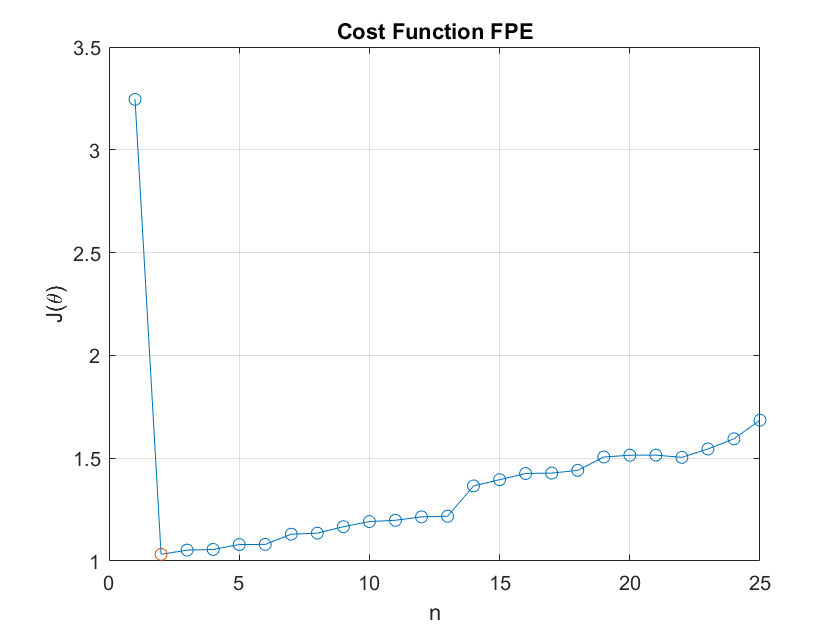

figure();
plot(J_PFE,'-o');
grid on;
hold on;
plot(n_min_FPE,J_PFE(n_min_FPE),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function FPE');

#### Akaike information criterion AIC

AIC criterion belongs to the family of the criteria with complexity terms. These criteria are obtained by penalizing in some way the decrease of $J\left({\theta^ˆ }_N \right)$with increasing orders. The order giving the smalles value of the criterion is selected.

As regards AIC criterion:


$$\textrm{AIC}=N\;\log \left(J\left({\theta^ˆ }_N \right)\right)+2p$$


AIC and FPE are asympoyically equivalent. FPE and AIC don't give consistent estimates of n.

I used the simple function ***myAIC.m*** to make this.

L = 25;
J_AIC=zeros(L,1);
for n=1:L
    J_AIC(n)=myAIC(y(N/2+1:end),u(N/2+1:end),Theta_RWLS_III{n});
end

[value_AIC,n_min_AIC]=min(J_AIC);
disp([value_AIC, n_min_AIC]);

  159.7073    2.0000



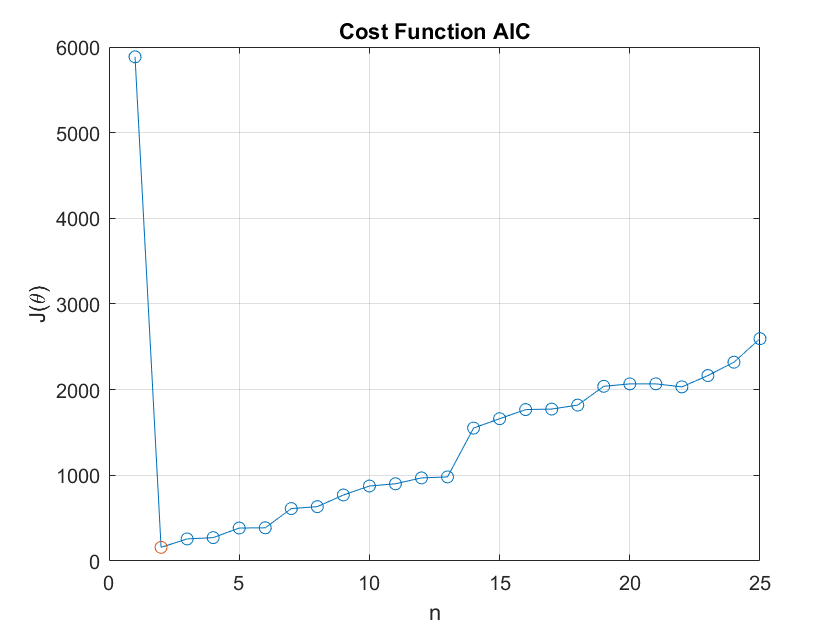


figure();
plot(J_AIC,'-o');
grid on;
hold on;
plot(n_min_AIC,J_AIC(n_min_AIC),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function AIC');

#### Minimum description length (MDL) criterion

MDL leads, in general, to models of lower complexity wrt AIC and FPE.

Even though the derivation is different, the MDL approach is formally equivalent to the bayesian information criterion (BIC).


$$\textrm{MDL}=N\;\log \left({\theta^ˆ }_N \right)+2p\;\log \left(N\right)$$


To do that, I used ***myMDL.m*** function.

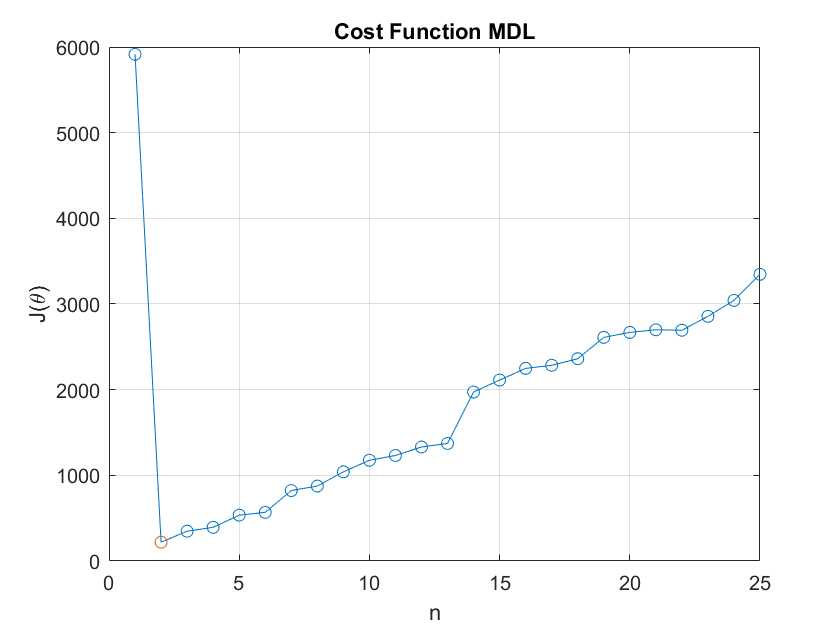

L = 25;
J_MDL=zeros(L,1);
for n=1:L
    J_MDL(n)=myMDL(y(N/2+1:end),u(N/2+1:end),Theta_RWLS_III{n});
end

[value_MDL,n_min_MDL]=min(J_MDL);

figure();
plot(J_MDL,'-o');
grid on;
hold on;
plot(n_min_MDL,J_MDL(n_min_MDL),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function MDL');

#### Order estimation

Once I computed all the criteria as we have done in the classes, I can choose the 'best' order (the minimum between all the orders):

best_order = min([n_min_FPE, n_min_AIC, n_min_MDL]);
fprintf('The "best order" is: %d\n',best_order)

The "best order" is: 2


The "best order" is 2, it means that the theta estimate is:

Theta_Best_order = Theta_RWLS_III{best_order};
Theta_Best_order

Theta_Best_order =     1.0270
    0.2882
    1.5511
    1.3180


### Exercise 1.4: **Validate the model**

***Model validation:*** It consists in evaluating the capability of the identified model to describe the process that has generated the data in a way compatible with its  planned use. In other words, we try to "validate" the chosen model structure.

Basic assumptions of Linear regression models:


$$y\left(t\right)=\varphi^T \left(t\right)\theta^* +\omega \left(t\right),\;\;\;\;\;\omega \left(t\right)\;\textrm{zero}-\textrm{mean}\;\textrm{and}\;\textrm{white}\Rightarrow E\left\lbrack u\left(t\right)\omega \left(t-\tau \;\right)\right\rbrack =0\;,\;\;\;\forall \;\tau \;$$


The LS estimate ${\theta^ˆ }_N$ is consistent, then:


$${\theta^ˆ }_N \to \theta^* ,\;\;\;\;\;\epsilon \left(t,{\theta^ˆ }_N \right)=y\left(t\right)-\varphi^T \left(t\right){\theta^ˆ }_N \to \omega \left(t\right),\;\;\;\;\;\;\textrm{when}\;N\to \infty$$


If we assume that our real data are well described by a linear regression model (as in our case), we can make the following assumptions about the residual $\epsilon \left(t,{\theta^ˆ }_N \right)$:

- $\;\epsilon \left(t,{\theta^ˆ }_N \right)$ is a zero mean white process;

- $\;\epsilon \left(t,{\theta^ˆ }_N \right)$ is uncorrelated with the input signal $u\left(t\right)$.

It is thus possible to perforem (on the training set) the following ***tests on residuals***:

- Test of whitness of $\;\epsilon \left(t,{\theta^ˆ }_N \right)$

- Test of cross-correlation between $\;\epsilon \left(t,{\theta^ˆ }_N \right)$ and $u\left(t\right)$

#### Whiteness test

Given a sequence of residuals: $\;\epsilon \left(1,{\theta^ˆ }_N \right),\;\epsilon \left(2,{\theta^ˆ }_N \right),\;\cdots \;\;,\epsilon \left(N,{\theta^ˆ }_N \right)$ (where N is the number of equations and not the total samples, in oher words, N is what in my notation I named N = #samples - n):


$$\left\lbrace \begin{array}{ll}
H_0 :\;\epsilon \left(t,{\theta^ˆ }_N \right) & \textrm{is}\;a\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{process}\\
H_1 :\textrm{not}\;H_0  & \left(\textrm{rejet}\;\textrm{the}\;\textrm{model}\;\right)
\end{array}\right.$$


Notice that if we reject the model ($H_1 \;\textrm{hypotesis}$), then we should repeat the test with a different order (or in general also with a different model but since for this exercise we are sure to deald with ARC model, I need only to change the order).

Consider the sample variance $\hat{r_{\epsilon \;} } \left(0\right)$ and the first *m* sample autocorreltaions of $\;\epsilon \left(t\right)$ and define the vector:


$$\hat{r_{\epsilon \;} } ={\left\lbrack \hat{r_{\epsilon \;} } \left(1\right)\;\;\;\hat{r_{\epsilon \;} } \left(2\right)\;\;\cdots \;\hat{r_{\epsilon \;} } \left(m\right)\right\rbrack }^T$$


Under $H_0$:


$$\hat{r_{\epsilon \;} } \left(0\right)\to {\sigma^2 }_{\omega \;} ,\;\;\;\;\;\;\hat{r_{\epsilon \;} } \left(\tau \right)\to 0\;\;\;\;\;\forall \tau \not= 0\;\;\;\;\;\;\;\textrm{when}\;N\to \infty \;$$


And it is possible prove that:


$$\sqrt{\;N}\hat{r_{\epsilon \;} } \to \sim N\left(0,P\right)\;\;\;\textrm{when}\;N\to \infty \;,\;\;\;P=\lim_{N\to \infty \;} E\left\lbrack N\hat{r_{\epsilon \;} } {\hat{r} }_{\epsilon \;}^T \right\rbrack =\sigma_{\omega \;}^4 I$$
    
$$\left(1\right)$$


In a compact form we could write:


$$\hat{r_{\epsilon \;} } =\frac{1}{N-m}\sum_{t=m}^N \epsilon \left(t,{\theta^ˆ }_N \right){\left\lbrack \epsilon \left(t-1,{\theta^ˆ }_N \right)\;\;\;\epsilon \left(t-2,{\theta^ˆ }_N \right)\;\;\cdots \epsilon \left(t-m,{\theta^ˆ }_N \right)\right\rbrack }^T$$


As consequence:


$$x=N\frac{\hat{r_{\epsilon \;} } {\hat{r} }_{\epsilon \;}^T }{{\hat{r} }_{\epsilon \;}^2 \left(0\right)}\;\to \chi {\;}^2 \;\left(m\right)\;\;\;\;\textrm{when}\;N\to \infty$$


This leads to the statistical test:


$$\left\lbrace \begin{array}{ll}
x\le \chi {\;}_{\alpha \;}^2 \;\left(m\right) & \Rightarrow \textrm{accept}\;H_0 \\
x>\chi {\;}_{\alpha \;}^2 \;\left(m\right) & \Rightarrow \textrm{reject}\;H_0 
\end{array}\right.$$


where $\alpha \;$is the chosen significance level.

A good possible choise, as said during the classes, could be $m=\frac{N}{4}$ when N is large enough (as in this case) and for $\alpha$ we pick 0.05.

I used ***myWhitenessChi.m*** to implement the test: here, given the residuals, I compute the autocorrelation and then I compute $x=N\frac{\hat{r_{\epsilon \;} } {\hat{r} }_{\epsilon \;}^T }{{\hat{r} }_{\epsilon \;}^2 \left(0\right)}$  and at the end I verified the test by using the Chi Square distribution.

% At first we need to compute all our residuals 
% eps_vector = Y - H*theta
alpha = 0.05;
Result_Chi = false;

while not(Result_Chi)
    
    m = round((N-best_order)/4);
    N_ = N-best_order;
    
    Hu = myHank(u,best_order); Hy = myHank(y,best_order);
    H_ARX = [-Hy, Hu];
    
    eps_vector = y(best_order+1:N) - H_ARX*Theta_RWLS_III{best_order};
    
    Result_Chi = myWhitenessChi(eps_vector,N_,m,alpha);
    
    if Result_Chi
        fprintf("The whiteness test (chi) is positive, then the order is: %d\n",best_order)
    else
        % because the model is ARX, we change the order since the test failed
        best_order = best_order + 1; % Naive way to change order 
        fprintf("The whiteness test (chi) is negative, change order in: %d\n", best_order)
    end
    
end

The whiteness test (chi) is positive, then the order is: 2


Alternatively, we could use many Gaussian tests!

Define the normalized test quantities:


$$\gamma^ˆ \left(\tau \right)=\frac{\hat{r_{\epsilon \;} } \left(\tau \right)}{{\hat{r} }_{\epsilon \;}^2 \left(0\right)},\;\tau =1,2,\cdots ,m$$


From (1) it follows that:


$$\sqrt{\;N}\gamma^ˆ \left(\tau \right)\to \sim N\left(0,1\right)\;\;\;\textrm{when}\;N\to \infty ,\;\;\;\tau =1,2,\cdots ,m\;$$


so that a set of *m *gaussian tests can also be perfomed.

For istance, if we choose $\alpha =0\ldotp 05$ (ad in our case) we have:


$$\left\lbrace \begin{array}{ll}
H_0^{\tau \;} :\left|\gamma^ˆ \left(\tau \right)\right|\le \frac{1\ldotp 96}{\sqrt{N}} & \;\\
H_1^{\tau \;} :\left|\gamma^ˆ \left(\tau \right)\right|>\frac{1\ldotp 96}{\sqrt{N}} & \;
\end{array},\;\;\;\;\tau =1,2,\cdots \;,m\right.$$


Where the 1.96 is given by the Gaussian distribution table.

To make the final decision, we can use the ***Anderson test***:


$$\left\lbrace \begin{array}{ll}
\bar{\frac{m}{m}} \le \alpha  & \Rightarrow \textrm{accept}\;H_0 \\
\bar{\frac{m}{m}} >\alpha  & \Rightarrow \textrm{reject}\;H_0 
\end{array}\right.$$


where $\bar{m}$ is the number of failed tests (whereas *m* is the number of total tests).

The whitness test can be of help if model order estimation, together with FPE, AIC and MDL.

To implement this test, I used the function ***myWhitenessAnderson.m***. As before, given the residuals, I computed the normalized autocorrelation and then I verified  each element of the latter by using the gaussian distribution and at the end I analyzed all the tests by usinf the Anderson test.

% At first we need to compute all our residuals 
% eps_vector = Y - H*theta
alpha = 0.05;
Result_Anderson = false;

while not(Result_Anderson)
    
    m = round((N-best_order)/4);
    N_ = N-best_order;
    
    Hu = myHank(u,best_order); Hy = myHank(y,best_order);
    H_ARX = [-Hy, Hu];
    
    eps_vector = y(best_order+1:N) - H_ARX*Theta_RWLS_III{best_order};
    
    Result_Anderson = myWhitenessAnderson(eps_vector,N_,m,alpha);
    
    if Result_Anderson
        fprintf("The whiteness (Anderson) test is positive, then the order is: %d\n",best_order)
    else
        % because the model is ARX, we change the order since the test failed
        best_order = best_order + 1; % Naive way to change order 
        fprintf("The whiteness (Anderson) test is negative, change order in: %d\n", best_order)
    end
    
end

The whiteness (Anderson) test is positive, then the order is: 2


If everything is ok (and actually it is), we can proceed with the next test

#### Test of cross-correlation


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,{\theta^ˆ }_N \right)\;\textrm{and}\;u\left(t\right)\;\textrm{are}\;\textrm{uncorrelated} & \;\\
H_1 :\textrm{not}\;H_0  & \;
\end{array}\right.$$


Consider the following vector of sample cross correlations:


$$\hat{r_{\epsilon u\;} } ={\left\lbrack \hat{r_{\epsilon \;u} } \left(\bar{\tau \;} +1\right)\;\;\;\hat{r_{\epsilon \;u} } \left(\bar{\tau \;} +2\right)\;\;\cdots \hat{r_{\epsilon \;u} } \left(\bar{\tau \;} +m\right)\right\rbrack }^T$$


Where $\tau^‾$ in this case is the order of the LS. 

Consider also the vector:


$$\varphi_u(t,m)=[u(t-1) \ u(t-2) \ \cdots \ u(t-m)]^T
$$
    

and the sample autocorrelation matrix $\hat{\Sigma_u } \left(m\right)$, which is an estimate of $E\left\lbrack \varphi_u \left(t,m\right){\varphi^T }_u \left(t,m\right)\right\rbrack$.

It is possible to prove that


$$\sqrt{\;N}\hat{r_{\epsilon \;u} } \to \sim N\left(0,P\right)\;\;\;\textrm{when}\;N\to \infty \;,\;\;\;P=\lim_{N\to \infty \;} E\left\lbrack N\hat{r_{\epsilon u\;} } {\hat{r} }_{\epsilon u\;}^T \right\rbrack =\sigma_{\omega \;}^2 \hat{\Sigma_u } \left(m\right)$$
    
$$\left(2\right)$$


As consequence:


$$x=N\frac{{\hat{r} }_{\epsilon u\;}^T \hat{{\Sigma^{-1} }_u } \left(m\right){\hat{r} }_{\epsilon u\;}^{\;} }{{\hat{r} }_{\epsilon \;}^{\;} \left(0\right)}\;\to \chi {\;}^2 \;\left(m\right)\;\;\;\;\textrm{when}\;N\to \infty$$


This leads to the statistical test:


$$\left\lbrace \begin{array}{ll}
x\le \chi {\;}_{\alpha \;}^2 \;\left(m\right) & \Rightarrow \textrm{accept}\;H_0 \\
x>\chi {\;}_{\alpha \;}^2 \;\left(m\right) & \Rightarrow \textrm{reject}\;H_0 
\end{array}\right.$$


where $\alpha \;$is the chosen significance level.

To do that, I used ***myCrossCorrChi.m***: Given the residuals and the inputs, I computed at first the estimate of the covariance matrix of the inputs by using $\hat\Sigma_u=\frac{(H^T_uH_u)}N$, and then I computed the crosscorrelation between the residuals and the input. Then I computed $x=N\frac{{\hat{r} }_{\epsilon u\;}^T \hat{{\Sigma^{-1} }_u } \left(m\right){\hat{r} }_{\epsilon u\;}^{\;} }{{\hat{r} }_{\epsilon \;}^{\;} \left(0\right)}$ and finally I examinated the Chi square distribution.

% At first we need to compute all our residuals 
% eps_vector = Y - H*theta
alpha = 0.05;
Result_Chi = false;
best_order = 2;

while not(Result_Chi)
    
    m = round((N-best_order)/4);
    N_ = N-best_order;
    
    Hu = myHank(u,best_order); Hy = myHank(y,best_order);
    H_ARX = [-Hy, Hu];
    
    eps_vector = y(best_order+1:N) - H_ARX*Theta_RWLS_III{best_order};
    
    Result_Chi = myCrossCorrChi(eps_vector,u,N_,m,alpha,best_order);
    
    if Result_Chi
        fprintf("The Cross-correlation (chi) test is positive, then the order is: %d\n",best_order)
    else
        % because the model is ARX, we change the order since the test failed
        best_order = best_order + 1; % Naive way to change order 
        fprintf("The Cross-correlation (chi) test is negative, change order in: %d\n", best_order)
    end
    
end

The Cross-correlation (chi) test is positive, then the order is: 2


As done for the whiteness test, no we will consider not only one chi square statistical test but many gaussian tests (and the Anderson one).

Define the normalized test quantities:


$$\gamma^ˆ \left(\tau \right)=\frac{{\hat{r} }_{\epsilon u\;}^{\;} \left(\tau \right)}{\sqrt{{\hat{r} }_{\epsilon \;}^{\;} \left(0\right){\hat{r} }_{u\;}^{\;} \left(0\right)}}$$


From (2), it follows that:


$$\sqrt{\;N}\gamma^ˆ \left(\tau \right)\to \sim N\left(0,1\right)\;\;\;\textrm{when}\;N\to \infty ,\;\;\;\tau =1,2,\cdots ,m\;$$


and then, as before, we can perform m gaussian tests and then analyze the results by using Anderson.

To do that I used ***myCrossCorrAnderson.m*** function.

% At first we need to compute all our residuals 
% eps_vector = Y - H*theta
alpha = 0.05;
Result_Anderson = false;

while not(Result_Anderson)
    
    m = round((N-best_order)/4);
    N_ = N-best_order;
    
    Hu = myHank(u,best_order); Hy = myHank(y,best_order);
    H_ARX = [-Hy, Hu];
    
    eps_vector = y(best_order+1:N) - H_ARX*Theta_RWLS_III{best_order};
    
    Result_Anderson = myCrossCorrAnderson(eps_vector,u,N_,m,alpha,best_order);
    
    if Result_Anderson
        fprintf("The Cross-correlation (Anderson) test is positive, then the order is: %d\n",best_order)
    else
        % because the model is ARX, we change the order since the test failed
        best_order = best_order + 1; % Naive way to change order 
        fprintf("The Cross-correlation (Anderson) test is negative, change order in: %d\n", best_order)
    end
    
end

The Cross-correlation (Anderson) test is positive, then the order is: 2


### ***Exercise 1: Conclusions***

***In conclusion***, my estimate is of order 2 and is:

Theta_Best_order = Theta_RWLS_III{best_order};
Theta_Best_order

Theta_Best_order =     1.0270
    0.2882
    1.5511
    1.3180


Let's check what are the ***statistical properties*** of a LS estimator of an ARX model.

Given the true model:


$$y\left(t\right)=\varphi^T \left(t\right)\theta^* +\omega \left(t\right)$$


it follows that:


$$\hat{\theta}=\theta^*+\left(\frac{1}{N}\sum_{t=1}^{N} \varphi(t) \varphi^{T}(t)\right)^{-1}\frac{1}{N} \sum_{t=1}^{N} \varphi(t) \omega(t)$$
    

The estimate is biased: $E[\hat{\theta}] \neq \theta^*$.

***Consistency***:


$$\lim_{N\rightarrow\infty}{\hat{\theta}_N =\theta^*+E[\varphi(t)\varphi^T(t)]^{-1}E[\varphi(t)\omega(t)]=\theta^*+\Sigma^{-1}_{\varphi}r_{\varphi\omega}$$


Where  $\Sigma^{-1}_{\varphi} \ and \ r_{\varphi\omega}$ are the covariance matrix and the cross-correlation respectively.

If $u(t)$ is p.e. of at least order *n* (as in this case), and if $\omega(t)$ $\Longrightarrow$$\Sigma_\varphi$invertible and $r_{\varphi\omega} = 0$, therefore


$$\lim_{N\rightarrow\infty}{\hat\theta}=\theta^*
$$


It is also possible to prove that:


$$\sqrt{N}(\hat\theta-\theta^*)\rightarrow\mathcal{N}(0,P), \ for \ N\rightarrow \infty$$


with


$$P = \sigma^2_\omega\Sigma^{-1}_\varphi$$


A consistent estimate of $\sigma^2_\omega$ is given by


$$\hat\sigma^2_\omega=J(\hat\theta)$$


then, $cov(\hat\theta)$can be estimated as


$$\hat{cov(\hat\theta)}=\frac{\hat\sigma^2_\omega\hat\Sigma^{-1}_\varphi}{N}=\hat\sigma^2_\omega(H^TH)^{-1}$$


Estimate_cov = myCostFunc(y,u,Theta_Best_order)*pinv(H_ARX'*H_ARX)

Estimate_cov = 	1.0e+-4 *

    0.3104    0.0820    0.0020    0.4806
    0.0820    0.0566    0.0013    0.1275
    0.0020    0.0013    0.1017    0.0023
    0.4806    0.1275    0.0023    0.8457


As we can notice, the diagonal elements are very small, and so the dispersion should be small, thus we can state that our estimate is reliable.

## Exercise 2: Classification (Only for LEDS students)

In this exercise you are asked to create a classificator from a training set and test it on a new test set..

To gather your set of labelled features at any point in your code call the function `ClassifyThis.p `with the following inputs:

- Number of samples (`integer`)

N=5000;

- Your surname and name with no accents nor special characters (`string`)

Student = 'Bamundo Salvatore';

- Your matriculation number (`string`)

Matriculation = '0000983702';

which finally results in

[FeatureSet] = ClassifyThis(N,Student,Matriculation);

To collect the set it is advised to use this piece of code

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

Ntrain = length(Utrain);
Ntest = N - Ntrain;

Then, the classification problem should be solved following the step below:

- **Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

- **Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to classify using logistic regression with the Newton-Raphson algorithm (In this case, remember to start the algorithm with theta as a vector of zeros).

- **Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results and compute the related classification error since you are provided with Ytest this time.

Remember to add a brief description of the matlab function you implemented accordingly.

**P.S.: **Remember that $\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T}$ in the case of complex curves.

Write an organic **Surname_Name.mlx **file contaning both the explanation and coding that follows the above steps of **BOTH** exercises. This will also be your final project report. Remeber to read carefully the exam description with the submission rules.

### Exercise 2.0: Introduction

Before starting with the exercise, let's introduce the concept of *classification.*

***Classificaion:*** assign the input $u\left(t\right)\in U$ to one of the $M$ ckasses (or categries) $C_1 ,C_2 ,\cdots ,C_M$. The input is numerical and the output is categorical.

Available data:


$$\left(u\left(1\right),y\left(1\right)\right),\left(u\left(2\right),y\left(2\right)\right),\cdots ,\left(u\left(N\right),y\left(N\right)\right)$$


A possible way to represent class labels numerically is:


$$y\left(t\right)=y^i \;\;\;\;\;\textrm{if}\;\;\;\;u\left(t\right)\in C_i$$


Where $y^i$ is a $M\times \;1$ vector whose elements are zero except the $i-\textrm{th}$ element, which is equal to 1. For a two-class problem we will use:


$$y\left(t\right)=\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;u\left(t\right)\in C_1 \\
0 & \textrm{if}\;u\left(t\right)\in C_2 
\end{array}\right.$$


The input space $U$ is divided into M regions labeled according to the classification rule. The boundaries of these regions are called ***decision boundaries***.

There exist two types of decision boundaries: Linear decision boundaries and nonlinear decision boundaries.

### Exercise 2.1: **Understand the feature set in space**

At first, let's check what is the plot in order to understand what type of decision boundary I should apply:

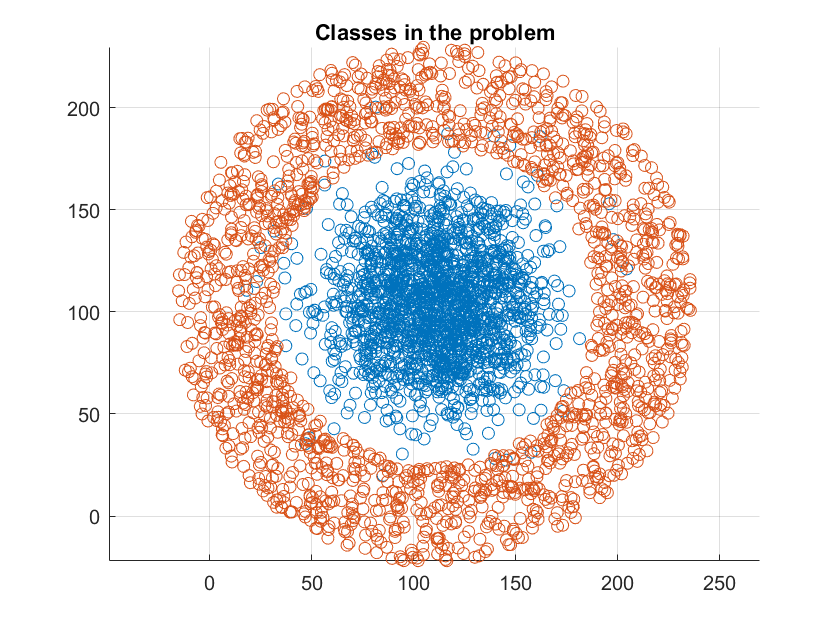

figure();
hold on 
plot(Utrain(find(Ytrain<0.5),1),Utrain(find(Ytrain<0.5),2), 'o');
plot(Utrain(find(Ytrain>0.5),1),Utrain(find(Ytrain>0.5),2),'o');
% plot(Utrain(1:end,1),Utrain(1:end,2),'o'); 
grid on 
hold off
title('Classes in the problem');
axis equal

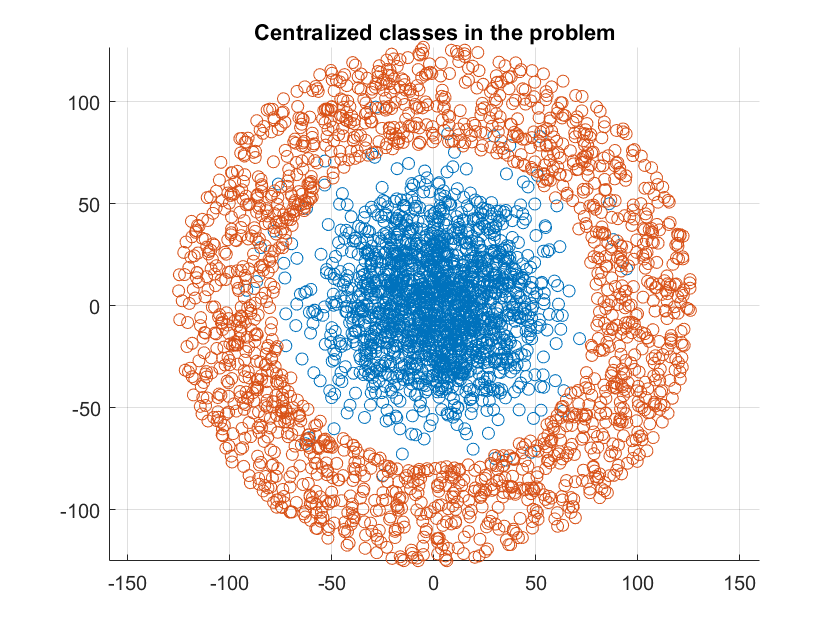

% Centralized Input samples to better make the next computations
x_disp = mean(Utrain(:,1));
y_disp = mean(Utrain(:,2));
Utrain_origin = [Utrain(1:end,1) - x_disp, Utrain(1:end,2) - y_disp];
Utest_origin = [Utest(1:end,1) - x_disp, Utest(1:end,2) - y_disp];
figure(); 
hold on
plot(Utrain_origin(find(Ytrain<0.5),1),Utrain_origin(find(Ytrain<0.5),2),'o');
plot(Utrain_origin(find(Ytrain>0.5),1),Utrain_origin(find(Ytrain>0.5),2),'o');

grid on 
title('Centralized classes in the problem');
axis equal

It is easy to see from the plot that we are dealing with a nonlinear decision boundary: it is a 2-classes classification problem with an ***elliptic nonlinear decision boundary in ***$R^2$.

#### Logistic regression

At first, let's introduce the concept of logistic regression.

Consider a two-classes classification problem with $r\;$inputs $u\left(t\right)={\left\lbrack u_1 \left(t\right)\;u_2 \left(t\right)\cdots u_r \left(t\right)\right\rbrack }^T$ and assume a linear decision boundary (not our case). This boundary is described by this equation:

$\beta_{0}+\beta_{1} u_{1}(t)+\beta_{2} u_{2}(t)+\cdots+\beta_{r} u_{r}(t)=0$.

that is 


$$\varphi^T \left(t\right)\theta =0$$


with $\varphi(t)=\left[1 \quad u_{1}(t) \quad u_{2}(t) \quad \cdots \quad u_{r}(t)\right]^{T}
$ and $\theta=\left[\beta_{0} \quad \beta_{1} \quad \cdots \quad \beta_{r}\right]^{T}$

How to model $P\left(C_1 \left|u\left(t\right)\right.\right)$, namely, the probability that given an input, it belongs to the class $C_1$ ?

We need a function $f\left(z\left(t\right)\right)$, where $z\left(t\right)=\varphi^T \left(t\right)\theta$, such that:

- $f\left(z\right)$ takes values in the range (0,1)

- 
$$f\left(0\right)=0\ldotp 5$$


- 
$$f\left(z\right)>0\ldotp 5\;\;\left(f\left(z\right)<0\ldotp 5\;\right)\;\textrm{when}\;z>0\;\left(z<0\right)$$


- 
$$f\left(z\right)\;\to 1\;\textrm{when}\;z\to \infty \;$$


- 
$$f\left(z\right)\;\to 0\;\textrm{when}\;z\to -\infty$$


We use the ***Logistic Sigmoid Function***:


$$f(z)=\frac{e^{z}}{1+e^{z}}=\frac{1}{1+e^{-z}}$$


with $z(t)=\varphi^{T}(t) \theta$.

In the following, I implemented **mySigmoid.m** function.

 z = 0;
 f = mySigmoid(z); 

We have now that 


$$P\left(C_1 \left|u\left(t\right)\right.\right)=f\left(z\left(t\right)\right),\;\;\;\;\;P\left(C_2 \left|u\left(t\right)\right.\right)=1-f\left(z\left(t\right)\right)=\frac{1}{1+e^z }$$


and


$$z\left(t\right)=\log \frac{P\left(C_1 \left|u\left(t\right)\right.\right)}{P\left(C_2 \left|u\left(t\right)\right.\right)}=$$

$$\log \frac{f\left(z\right)}{1+f\left(z\right)}$$


Before introducing the requested algorithm, let's discuss about how can we deal with nonlinear boundaries (as in our case).

By means of a nonlinear transformation in the input space:


$$u\left(t\right)\in U\to \bar{u} \left(t\right)=g\left(u\left(t\right)\right)\in U$$


a nonlinear boundary $U$can be mapped into a linear one in $\bar{U}$. The logistic regression is then applied to the transformed inputs.

in our case we have a ellipse, and so, the nonlinear boundary is expressed as:


$$\beta_0 +\beta_1 u_1^{\;} \left(t\right)+\beta_2 u_2^{\;} \left(t\right)+\beta_3 u_1^2 \left(t\right)+\beta_4 u_2^2 \left(t\right)=0$$


and so 

$\varphi(t)=\left[1 \quad u_1(t) \quad u_2(t) \quad u^2_{1}(t) \quad u^2_{2}(t) \right]^{T}
$.

we obtain: 


$$\bar\varphi(t)=g(\varphi(t))=\left[1 \quad \bar u_{1}(t) \quad \bar u_{2}(t)   \quad \bar u_{3}(t) \quad  \bar u_{4}(t)  \right]^{T}
$$
 

and so:


$$\beta_{0}+\beta_{1} \bar u_{1}(t)+\beta_{2} \bar u_{2}(t)+\beta_{3} \bar u_{3}(t)+\beta_{4} \bar u_{4}(t)=0$$


It is linear in $R^4$. In this case It needs only to apply the Newton-Raphson method considering the problem as linear in $R^4$. By applying the latter algorithm I obtain the values of theta (this method is applied in the "***Extra part***" of this exercise).

But there is also another approach, that I used at first, for dealing with nonlinear two-dofs boundaries in $R^2$.

Instead of "linearizing" $\varphi(t)$, I generated, from the input samples in $R^2$, a quadratic function in $R^3$. The main gol is that, after this transformation to the higher dimensional space, I can split the classes only by using a plane (aka a linear boundary and so the Newton-Raphson method as requested).

Notice that this method is based on the kernel trick but it is not applied to the SVM as usual.

In this case, I used, as trasformation. the following:


$$\psi \left(\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
u_1^2 \\
\sqrt{2}u_1 u_2 \\
u_2^2 
\end{array}\right\rbrack$$


Let's check what happens if I apply this quadratic mapping to our inputs: 

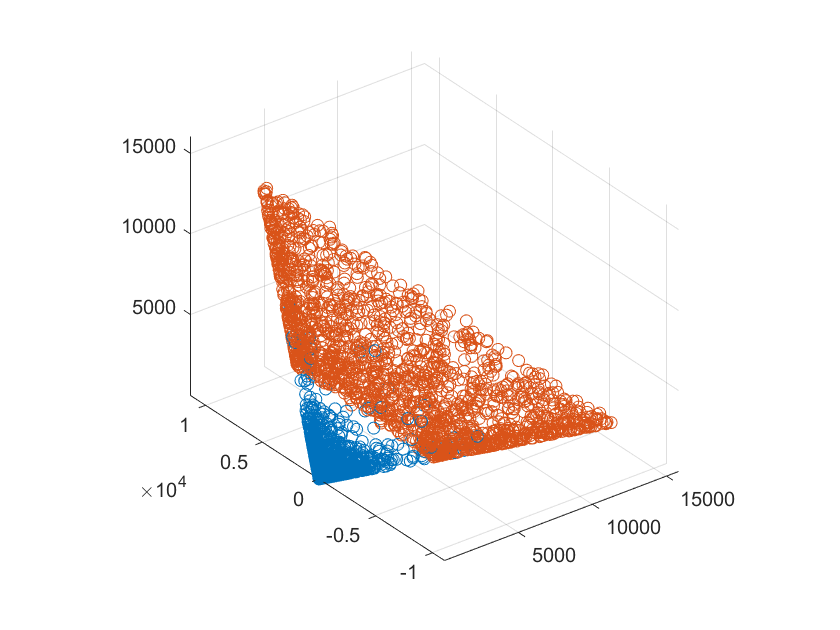

X_train = Utrain_origin(:,1).^2;
Y_train = sqrt(2).*Utrain_origin(:,1).*Utrain_origin(:,2);
Z_train = Utrain_origin(:,2).^2;

Utrain_origin_new = [X_train,Y_train,Z_train];

X_test = Utest_origin(:,1).^2;
Y_test = sqrt(2).*Utest_origin(:,1).*Utest_origin(:,2);
Z_test = Utest_origin(:,2).^2;

Utest_origin_new = [X_test,Y_test,Z_test];

figure
hold off
plot3(Utrain_origin_new(find(Ytrain<0.5),1),Utrain_origin_new(find(Ytrain<0.5),2),Utrain_origin_new(find(Ytrain<0.5),3),'o');
hold on
plot3(Utrain_origin_new(find(Ytrain>0.5),1),Utrain_origin_new(find(Ytrain>0.5),2),Utrain_origin_new(find(Ytrain>0.5),3),'o');
%plot3(X_train,Y_train,Z_train,'o')
grid on
axis equal
hold off

As I expected, now I am dealing with a classification problem that can be dealt with a linear boundary in $R^3$, aka a plane:


$$\beta_0 +\beta_1 u_1 +\beta_2 u_2 +\beta_3 u_3 =0$$


### **Exercise 2.2: Define the required classification algorithm**

#### The Newton-Raphson algorithm

To estimate $\theta$ we need to maximize the poster probability of the observation $Y={\left\lbrack y\left(1\right)\;y\left(2\right)\;\cdots y\left(N\right)\right\rbrack }^T$.

To make it, I will use ***Maximum Likelihood Estimation***


$$J(\theta)=\log P(Y \mid \theta)=\sum_{t=1}^{N}[y(t) \log f(z(t))+(1-y(t)) \log (1-f(z(t)))]$$


% Since I am now in a R3 case, to initialize Theta I need 4 parameters
Theta_init = [0; 0; 0; 0];
PHITrain=[ones(Ntrain,1) Utrain_origin_new];
J_init = myLRCostFunc(PHITrain,Ytrain,Theta_init);

Maximize the above function is equivalent to minimize its negative, so we have to find the estimate $\theta^ˆ$ minimizing:


$$J\left(\theta \right)=-\textrm{logP}\left(Y\left|\theta \right.\right)$$


To solve this optimization problem we can use the ***Newton-Raphson algorithm***:


$${\theta^ˆ }^{k+1} ={\theta^ˆ }^k -\alpha_k {J^{\prime } }^{\prime } {\left({\theta^ˆ }^k \right)}^{-1} J^{\prime } {\left({\theta^ˆ }^k \right)}^T$$


Before writing down this algorithm, we need to compute the gradient and the hessian of our cost function.

From the theory, we know, after some computations, that:


$$J^{\prime } \left(\theta \right)=\Phi^T \left(F\left(\theta \right)-Y\right)$$


where

$\Phi=\left[\begin{array}{cccc}
1& u(1) & \cdots & u(1) \\
1 & u(2) & \cdots & u(2) \\
\vdots & \vdots & \cdots & \vdots \\
1 & u(N) & \cdots & u(N)
\end{array}\right]$,    $Y=\left[\begin{array}{c}
y(1)\\
y(2) \\
\vdots \\
y(N)
\end{array}\right]$,    $F(\theta)=\left[\begin{array}{c}
f(z(1))\\
f(z(2)) \\
\vdots \\
f(z(N))
\end{array}\right]$

Whereas the Hessian is:


$$J^{\prime \prime } \left(\theta \right)=\Phi^T W{\left(\theta \right)\Phi }^{\;}$$


with


$$W\left(\theta \right)=\textrm{diag}\left\lbrack f\left(z\left(1\right)\right)\left(1-f\left(z\left(1\right)\right)\right)\;\;\;f\left(z\left(2\right)\right)\left(1-f\left(z\left(2\right)\right)\right)\;\;\cdots \;f\left(z\left(N\right)\right)\left(1-f\left(z\left(N\right)\right)\right)\right\rbrack$$


To compute the gradient and the hessian I used ***myLRCostFuncGrad.m*** and ***myLRCostFuncHessian.m*** respectively by using the above computations:

GradJ = myLRCostFuncGrad(PHITrain,Ytrain,Theta_init);
HessJ = myLRCostFuncHessian(PHITrain,Ytrain,Theta_init);

And now we can proceed with the implementation of the algorithm:

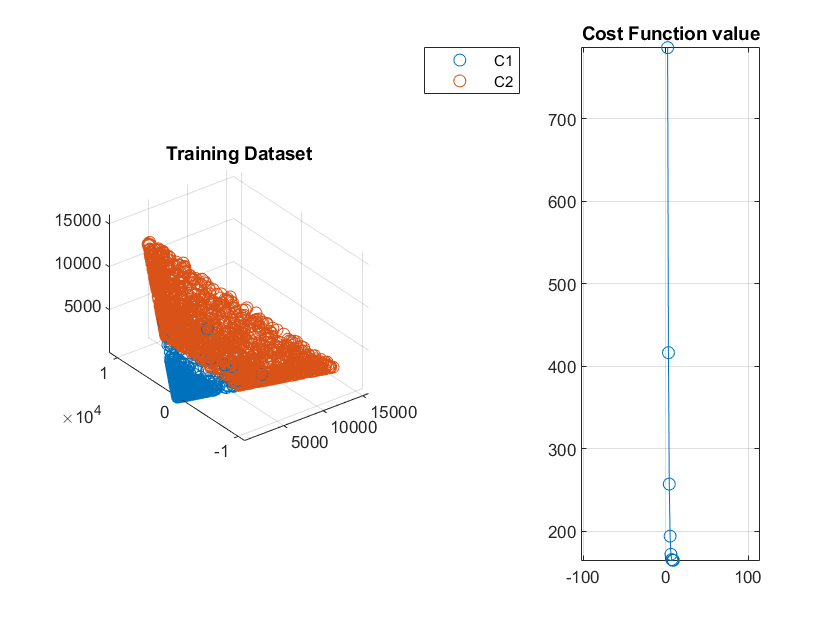

Alpha = 1;
J(1) = J_init;
k=2;
Theta = Theta_init;
figure();

while 1
    GradJ = myLRCostFuncGrad(PHITrain,Ytrain,Theta);
    HessJ = myLRCostFuncHessian(PHITrain,Ytrain,Theta);
    Theta = Theta - Alpha*pinv(HessJ)*GradJ; 
    J(k) = - myLRCostFunc(PHITrain,Ytrain,Theta);    
    
    if (abs(J(k)-J(k-1))<0.001)
        break;
    end
    subplot(1,3,[1 2]);
    hold off
    plot3(Utrain_origin_new(find(Ytrain<0.5),1),Utrain_origin_new(find(Ytrain<0.5),2),Utrain_origin_new(find(Ytrain<0.5),3),'o');
    hold on
    grid on 
    plot3(Utrain_origin_new(find(Ytrain>0.5),1),Utrain_origin_new(find(Ytrain>0.5),2),Utrain_origin_new(find(Ytrain>0.5),3),'o');
    % To plot also the variation of the Boundary plane, uncomment the
    % following 3 lines of code (it becomes very slow)
%     [xspace yspace] = meshgrid(-5000:3:5000);
%     BoundaryPlane = (Theta(1) + xspace.*Theta(2) +  yspace.*Theta(3))./(-Theta(4));
%     plot3(xspace,yspace,BoundaryPlane);
    axis equal
    hold off
    title('Training Dataset');
    legend({'C1','C2'});
    
    subplot(1,3,3);
    plot(2:k,J(2:k),'o-');
    grid on;
    title('Cost Function value')
    
    pause(0.1);
    k=k+1;
    axis equal
    
end

### **Exercise 2.3: Verify and test your classificator**

To test this classificator, I need to introduce the classification error also knonw as *error rate*;


$$E_r =\frac{1}{N}\sum_{t=1}^N I\left(y\left(t\right),\hat{y} \left(t\right)\right)$$


Where $\hat{y} \left(t\right)$ is the prediction of $y\left(t\right)$ provided by the classifier and $I\left(y\left(t\right),\hat{y} \left(t\right)\right)$ is an *indicator variable*:


$$I\left(y\left(t\right),\hat{y} \left(t\right)\right)=\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;y\left(t\right)\not= \hat{y} \left(t\right)\\
0 & \textrm{if}\;y\left(t\right)=\hat{y} \left(t\right)
\end{array}\right.$$


PHITest = [ones(Ntest,1) Utest_origin_new];
Yhat = mySigmoid(PHITest*Theta);
Yhat = double(Yhat>0.5);

ClassificationError = 1/(N)*((abs(Yhat-Ytest))'*(abs(Yhat-Ytest)))

ClassificationError = 0.0014

Notice that the classification error is very small, it is good.

Now I plot the results obtained and compare them to the test ones:

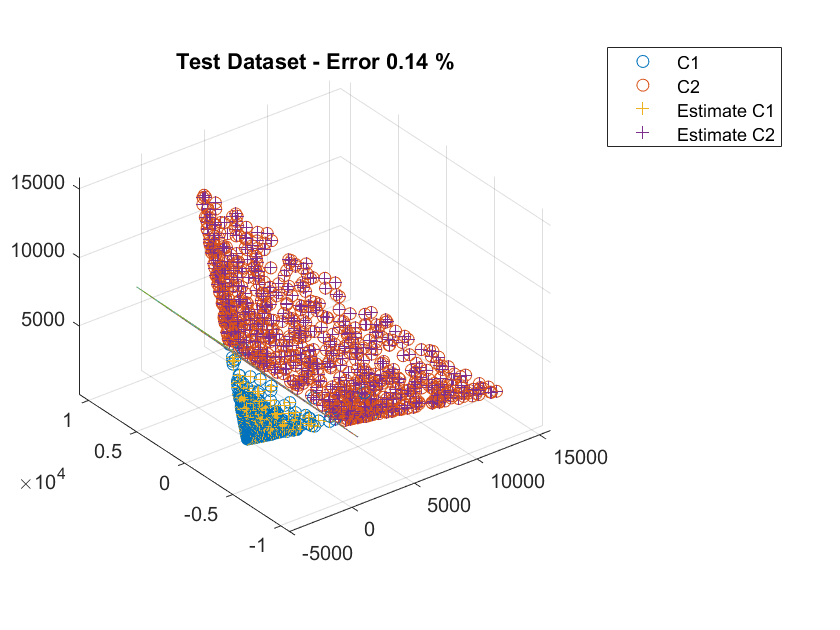

figure();
    hold off
    plot3(Utest_origin_new(find(Ytest<0.5),1),Utest_origin_new(find(Ytest<0.5),2),Utest_origin_new(find(Ytest<0.5),3),'o');
    hold on 
    grid on 
    plot3(Utest_origin_new(find(Ytest>0.5),1),Utest_origin_new(find(Ytest>0.5),2),Utest_origin_new(find(Ytest>0.5),3),'o');
    plot3(Utest_origin_new(find(Yhat<0.5),1),Utest_origin_new(find(Yhat<0.5),2),Utest_origin_new(find(Yhat<0.5),3),'+');
    plot3(Utest_origin_new(find(Yhat>0.5),1),Utest_origin_new(find(Yhat>0.5),2),Utest_origin_new(find(Yhat>0.5),3),'+');
    [xspace yspace] = meshgrid(-5000:3:5000);
    BoundaryPlane = (Theta(1) + xspace.*Theta(2) +  yspace.*Theta(3))./(-Theta(4));
    plot3(xspace,yspace,BoundaryPlane);
    Title =  sprintf('Test Dataset - Error %3.2f %%',ClassificationError*100);
    title(Title);
    legend({'C1','C2','Estimate C1', 'Estimate C2'},'location','bestoutside');
    hold off
    axis equal

As expected, the classification is very good and the error is smaller than 0.15%.

Although working with an additional dimension could result computationally more difficult, it works very well. 

At last, to have a good overview of what I have done, let's go back to the $R^2$ case for the test dataset:    

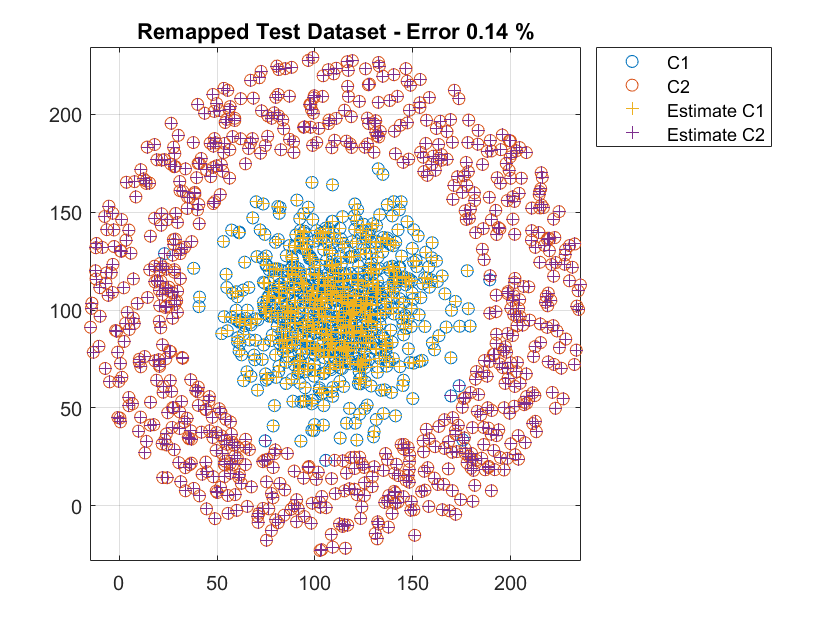

    plot(Utest(find(Ytest<0.5),1),Utest(find(Ytest<0.5),2),'o');
    hold on
    plot(Utest(find(Ytest>0.5),1),Utest(find(Ytest>0.5),2),'o');
    plot(Utest(find(Yhat<0.5),1),Utest(find(Yhat<0.5),2),'+');
    plot(Utest(find(Yhat>0.5),1),Utest(find(Yhat>0.5),2),'+');
    grid on 
    Title =  sprintf('Remapped Test Dataset - Error %3.2f %%',ClassificationError*100);
    title(Title);
    legend({'C1','C2','Estimate C1', 'Estimate C2'},'location','bestoutside');
    axis equal
    hold off    

### Exercise 2: Extra part, alternative solution

Let's consider now the first approach I explained:


$$\bar\varphi(t)=g(\varphi(t))=\left[1 \quad \bar u_{1}(t) \quad \bar u_{2}(t)   \quad \bar u_{3}(t) \quad  \bar u_{4}(t)  \right]^{T}
$$


where $\bar{u}_1(t)  = u_1(t), \ \bar{u}_2(t)  = u_2(t),\  \bar{u}_3(t)  = u_1^2(t)\  and\ \bar{u}_4(t)  = u_2^2(t)$:

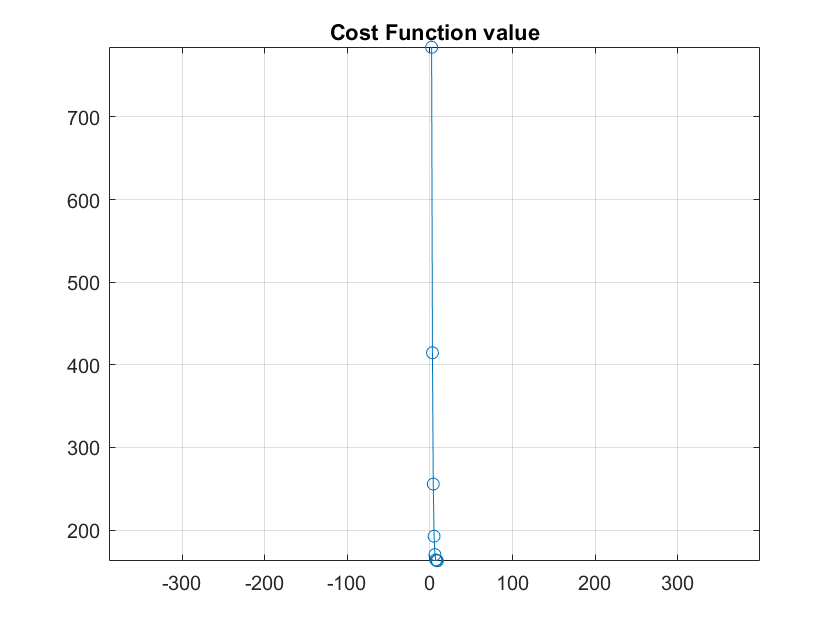

% Since I am now in a R4 case, to initialize Theta I need 5 parameters
Theta_init_Extra = [0; 0; 0; 0; 0];
PHITrain_Etra = [ones(Ntrain,1) Utrain(:,1) Utrain(:,2) Utrain(:,1).^2 Utrain(:,2).^2];
J_init_Extra = myLRCostFunc(PHITrain_Etra,Ytrain,Theta_init_Extra);

% Newton-Raphson method on the new phi of 5 parameters
Alpha = 1;
J_Extra(1) = J_init_Extra;
k=2;
Theta_Extra = Theta_init_Extra;
% x0 = 0;
% y0 = 0;
% ff  = 0;
figure();

while 1
    GradJ = myLRCostFuncGrad(PHITrain_Etra,Ytrain,Theta_Extra);
    HessJ = myLRCostFuncHessian(PHITrain_Etra,Ytrain,Theta_Extra);
    Theta_Extra = Theta_Extra - Alpha*pinv(HessJ)*GradJ; 
    J_Extra(k) = - myLRCostFunc(PHITrain_Etra,Ytrain,Theta_Extra);    
    
    if (abs(J_Extra(k)-J_Extra(k-1))<0.001)
        break;
    end
    
    plot(2:k,J_Extra(2:k),'o-');
    grid on;
    title('Cost Function value')
    
    pause(0.1);
    k=k+1;
    axis equal
    
end

PHITest_Extra = [ones(Ntest,1) Utest(:,1) Utest(:,2) Utest(:,1).^2 Utest(:,2).^2];
Yhat_Extra = mySigmoid(PHITest_Extra*Theta_Extra);
Yhat_Extra = double(Yhat_Extra>0.5);

ClassificationError_Extra = 1/(N)*((abs(Yhat_Extra-Ytest))'*(abs(Yhat_Extra-Ytest)))

ClassificationError_Extra = 0.0014

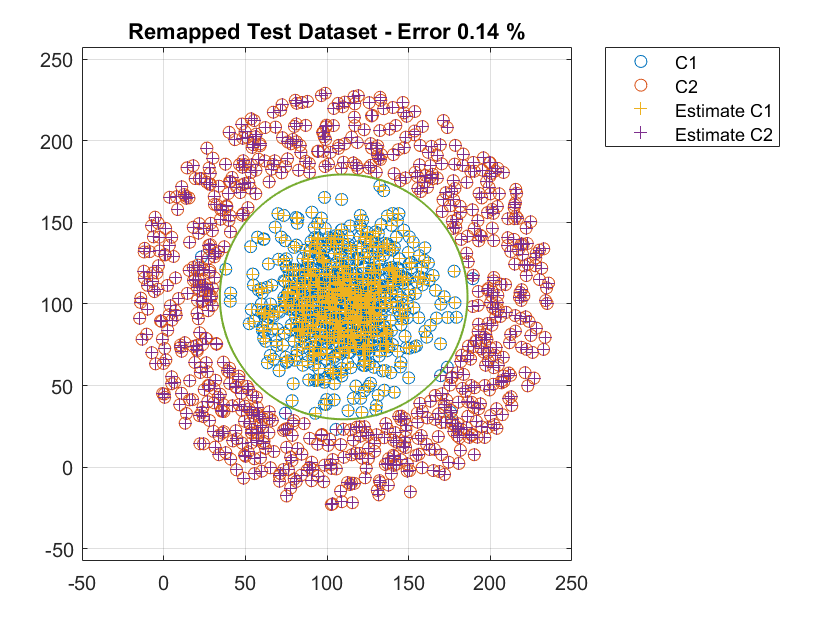

% To represent the ellipse that has, as coefficients, Theta_Extra
syms xx yy
fff = Theta_Extra(1)+Theta_Extra(2)*xx+Theta_Extra(3)*yy+Theta_Extra(4)*xx^2+Theta_Extra(5)*yy^2;

% Plot everything
plot(Utest(find(Ytest<0.5),1),Utest(find(Ytest<0.5),2),'o');
hold on
plot(Utest(find(Ytest>0.5),1),Utest(find(Ytest>0.5),2),'o');
plot(Utest(find(Yhat_Extra<0.5),1),Utest(find(Yhat_Extra<0.5),2),'+');
plot(Utest(find(Yhat_Extra>0.5),1),Utest(find(Yhat_Extra>0.5),2),'+');
Xlim = xlim();
Ylim = ylim();
fimplicit(fff,[Xlim(1) Xlim(end) Ylim(1) Ylim(end)], '-', 'LineWidth',1)
grid on 
Title =  sprintf('Remapped Test Dataset - Error %3.2f %%',ClassificationError_Extra*100);
title(Title);
legend({'C1','C2','Estimate C1', 'Estimate C2'},'location','bestoutside');
axis equal
hold off    

The result is very good, and the error is the same than the first method I used.

In conclusion, I can state that both the methods are good since the error is less than 0.15%.